# MOBATSim Documentation

**Welcome to MOBATSim documentation!**

MOBATSim (Model-based Autonomous Traffic Simulation Framework) is a simulation framework based on MATLAB® Simulink® that allows the user to assess vehicle level and traffic level safety by a 3D traffic simulation. Automated driving systems tend to be more important and sophisticated in the nearest future. The functional safety assessment for these systems becomes an urgent necessity for the transition to full autonomy. Testing these functions consisting of decision and control algorithms with a lot of variables and parameters in a unified manner is a daunting task. Threat assessment has to be made for vehicles to actively avoid hazardous situations. This requires the analysis of complex operational profiles such as routing, intersection management and collision prediction in an environment where multiple vehicles are in different positions, and traveling at different speeds. There is a need for a comprehensive traffic simulation framework which models not only the functionality of the vehicles but also the interactions between them.

More detailed information about the scientific papers related to MOBATSim can be found on this website: [https://mobatsim.com/](https://mobatsim.com/)

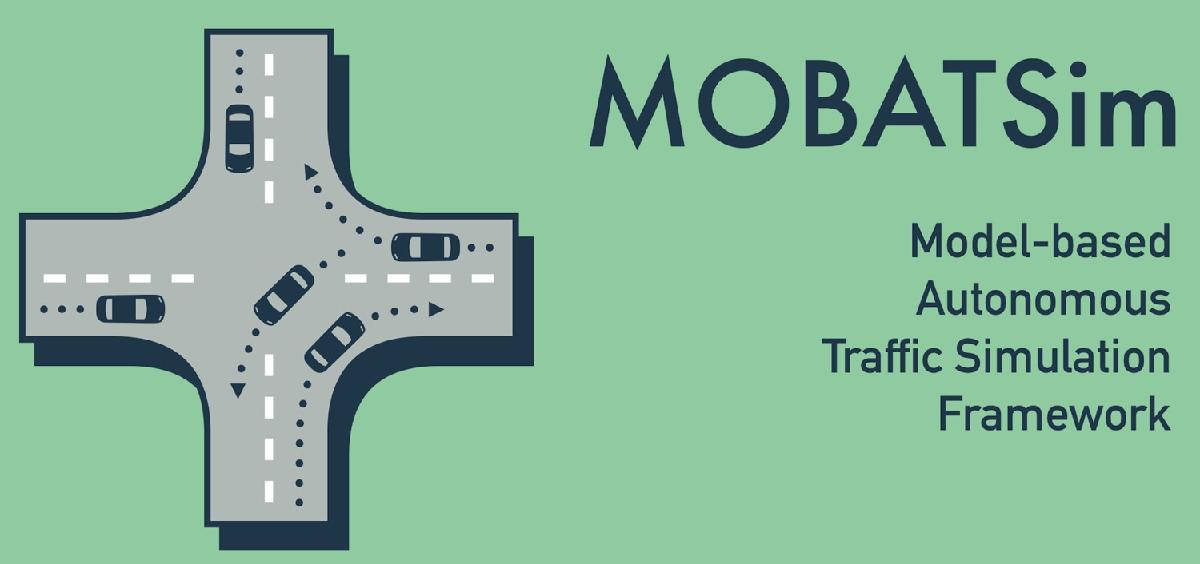

## Overview

MOBATSim has a project file which includes the Simulink files and their paths. As you run `MOBATSim.prj`, a GUI will open and you can run simulations from that GUI. However, if you are new to MOBATSim and want to go through the guides to see how it works, jump to section Workflow.

The code is commented out so that you don't automatically run it.

%uiopen('\MOBATSim_OpenSource.prj',1) 

If you want to open the Project and skip the Workflow rather than going step by step then copy and paste the command `uiopen('\MOBATSim_OpenSource.prj',1)` into the command windows. Otherwise, go down to the Workflow Chapter.

## Author

Main Author: Mustafa Saraoğlu

## Copyright Notice

© 2017 MOBATSim.

### **Please cite as:**

Saraoglu, M., Morozov, A., & Janschek, K. (2019). MOBATSim: MOdel-Based Autonomous Traffic Simulation Framework for Fault-Error-Failure Chain Analysis. IFAC-PapersOnLine, 52(8), 239–244. Elsevier BV. Retrieved from https://doi.org/10.1016%2Fj.ifacol.2019.08.077

# Requirements

### MATLAB Version Requirement

MOBATSim is continuously updated with the newest version of MATLAB®. Therefore, at this moment, the requirement is MATLAB 2020a.

### Toolbox Requirements

- Simulink 3D Animation Toolbox™ (Only required for the 3D Animation Model)

- Model Predictive Control Toolbox™  (will be soon required)

- Simulink Coverage™ (will be required in the next versions for testing and code coverage analyses)

# Model Architecture

## Simulation Framework

An overview of the simulation framework is shown in the figure below. For more details, please refer to: [https://mobatsim.com/about-mobatsim/](https://mobatsim.com/about-mobatsim/)

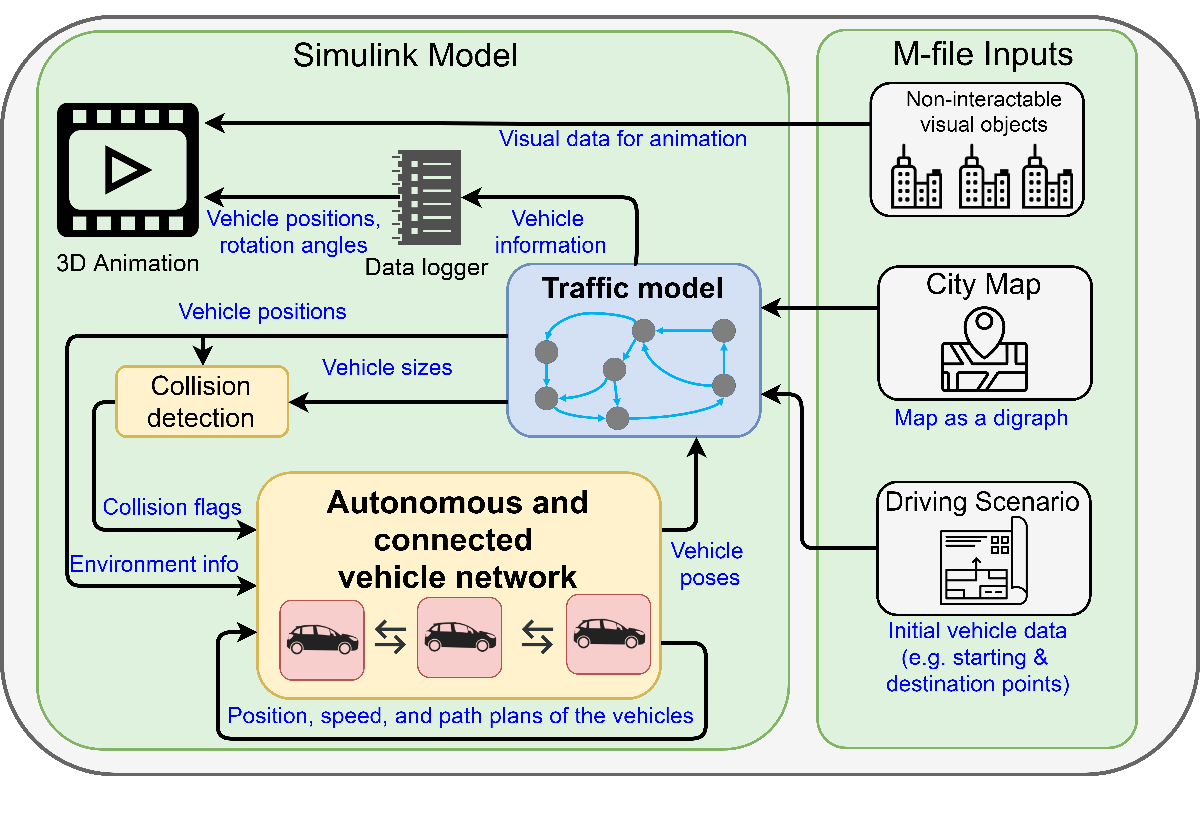

## Traffic Model

The traffic model of MOBATSim is an m-file which contains checkpoints and the routes between these points. The structure is converted into a digraph consisting of nodes and edges. The nodes are the points which are then used by the vehicles as starting and ending points. The edges are one-way routes between these nodes and are defined either as straight roads or curves. The local trajectory planner of the vehicle first uses its pathfinding algorithms to derive a path (depends on the customized algorithm, either by choosing the shortest path or the fastest path) and then derives the checkpoints and the routes to use.

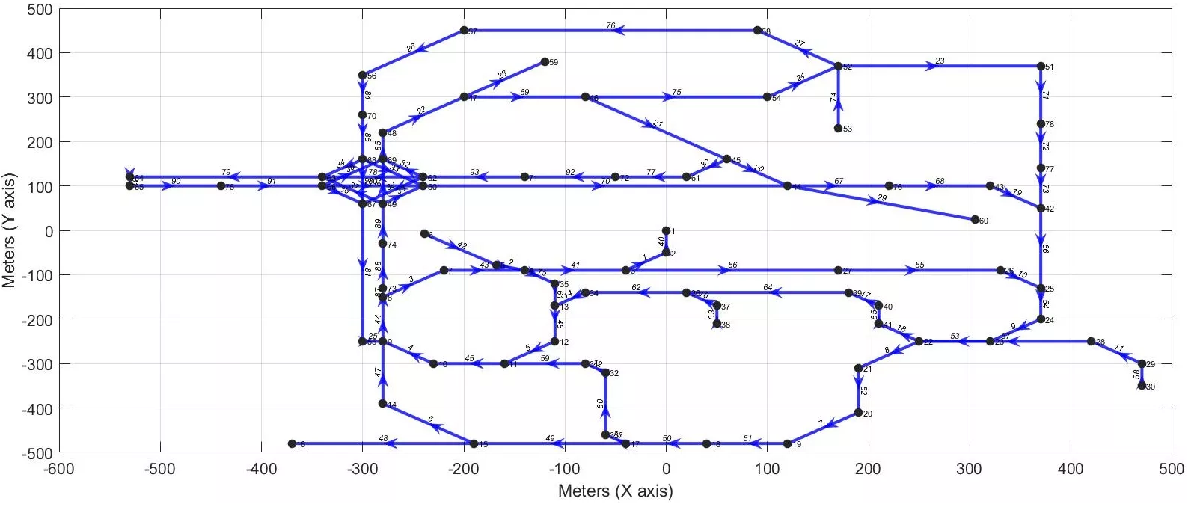

The generation of this map file is done by SolidWorks 2D Sketch. Then the sketch is exported into an m-file by defining the cartesian coordinates of the nodes and the shapes of edges(either straight roads or curves). This format is defined for a 2D visualization during the simulation and it the pathfinding algorithms of the vehicles can read it. The 2D sketch can be made 3D using the SolidWorks and then exported into the virtual world format for MATLAB V-Realm Editor. Click here to read about the 3D World and Simulink 3D Animation.

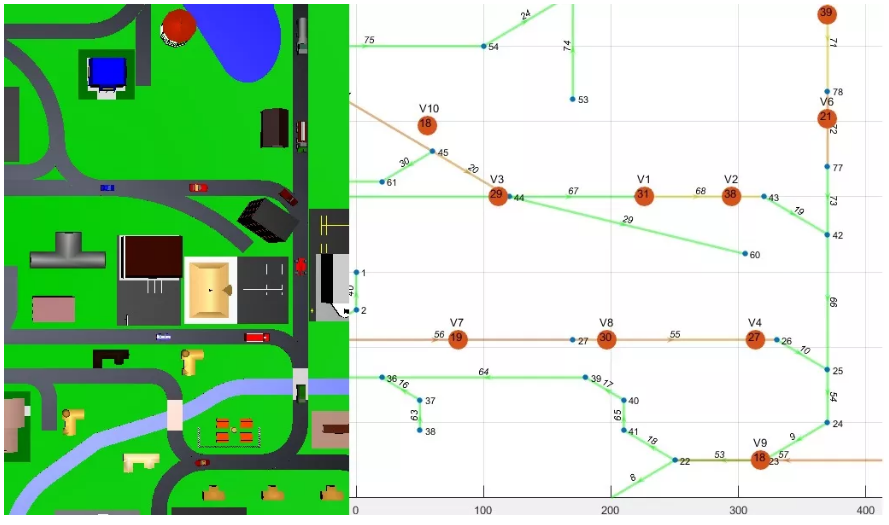

## Autonomous Vehicle Model in MOBATSim

The structure of an autonomous vehicle in MOBATSim consists of different abstraction levels. The reason for this abstraction is to allow the user to easily access and customize the low-level components, their inputs/outputs, and the implemented decision and control algorithms by clear interfaces between these components and subsystems shown in the figure. There four main interfaces; Perception, Decision-making, Trajectory Planner and Communication Output.

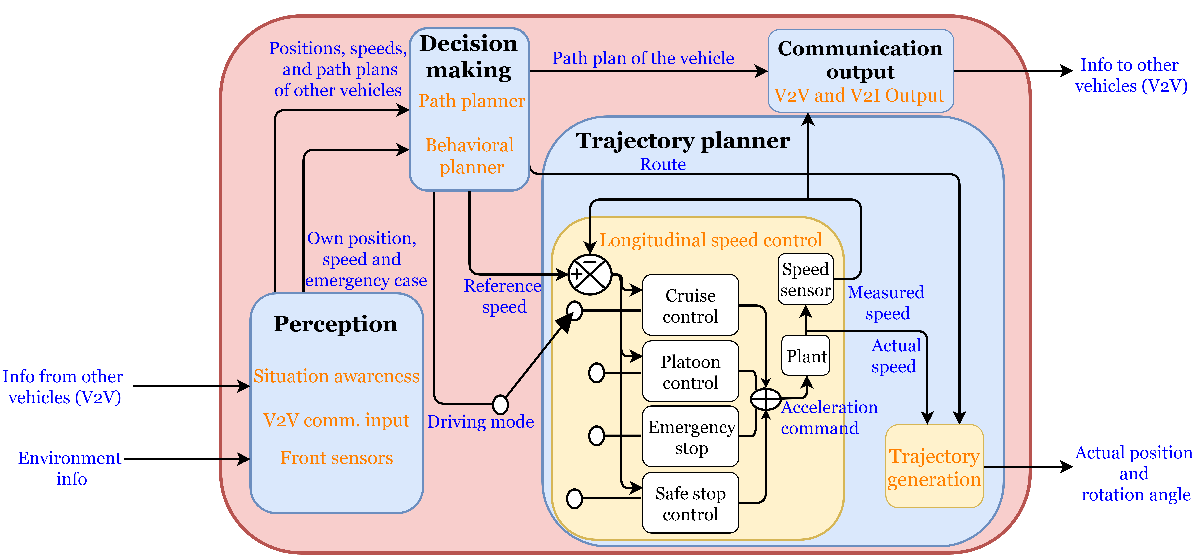

### The Perception Interface

The Perception Interface consists of three main components; Front sensors, V2V communication input, and Situation awareness. Vehicles perceive the environment in two ways, namely by their front sensors and V2V communication components. The Situation awareness component processes the perceived data in order to assess the emergency case of the vehicle and its relative situation according to the other vehicles around.

### The Decision-making Interface

The decision-making part consists of a Path planner and a Behavioral planner. Path planner uses the embedded estimation and pathfinding algorithms to make the decision for the route to be taken by the vehicle. The Behavioral planner takes the input data about the perceived situation of the vehicle and generates the driving command inputs to determine the driving mode of the vehicle (e.g. cruise control, platooning, emergency brake, approaching an intersection). According to the driving mode, the relevant subsystem of the longitudinal speed control adjusts the acceleration commands in order to generate the desired longitudinal speed.

### The Trajectory Planner Interface

It consists of a Longitudinal speed control subsystem and a Trajectory generation component. The Longitudinal speed control consists of four main parts. These parts function according to the driving mode command created by the behavioral planner component of the decision-making interface. There are mainly four driving modes available: cruise control, platooning control, safe stop control and emergency stop.

Cruise control is the mode where there is no vehicle ahead. In this mode, the vehicle accelerates to reach its top speed. As long as the front sensor does not sense any vehicle ahead or V2I component of the vehicle does not receive a stop message before an intersection, the vehicle keeps going at its top speed.

When the vehicle has to follow a slower vehicle, the platooning control takes over to generate the acceleration commands to form a stable platoon. There a number of algorithms that can be implemented for following a vehicle and keeping a safe distance. At the moment MOBATSim offers three variations: constant space by PID, constant headway time by PID and constant headway time by MPC. All these control algorithms can be tuned in order to implement more aggressive or more robust vehicle following behaviors.

Safe stop control starts where the vehicle receives a stop message and has to stop before an intersection in case the other vehicles have the right of way to cross the intersection. It helps vehicles slow down softly before a designated stop node.

The emergency stop utilizes full brakes when the vehicle ahead stops suddenly or another vehicle suddenly cuts in. Then the emergency stop part generates a constant deceleration command.

The selected route and the longitudinal speed are taken as inputs by the trajectory generation component to create the longitudinal and rotational motions. A pose vector consisting of an x-y-z coordinate position and a rotation angle is created for the purpose of the simulation.

### Communication Output Interface

The current values of position, speed and path plans of the vehicle are then packed by the V2V communication output component and shared with the rest of the network of connected vehicles. The importance of sharing the path plans of the vehicles is to predict the traffic jams and choose a route which reaches the destination node in the shortest time possible. At this moment the V2I component is only used to cross intersections. AIM (Autonomous Intersection Management) sends and receives messages and uses its own algorithms to give the right of the way to the incoming vehicles.

# Workflow

## How to run a Simulation

When you run this script, you will automatically run the default scenario of a traffic simulation on MOBATSim. However, the intended purpose of this script is to understand the main workflow of the software, so I suggest you use the `Run and Advance` command above for this live script, rather than the `run` command.

First, we have to add the paths of the functions which are in `src` folder, and images in `img` folder. Then we make sure that our `workspace` is clear and no `figure` is already on hold. 

%% Init file for MOBATSim
addpath(genpath('./src'));
addpath(genpath('./img'));

hold off; % To make sure that we don't edit any existing figures
warning off

clear all; % To make sure that our workspace is clear, there is a warning message but ignore it. 
% Because we have to use this to delete the all hidden handles of the map.

simSpeed = 4; % For scaling the simulation speed
Sim_Ts = 0.01; % Sample time of the simulation (may not be stable if changed)

modelName = 'MOBATSim'; %This variable will be used to get the right Simulink Model by name.

Remember that we will be running the simulation from an alternative way. Therefore, some variables that exist in the `GUI` variation may not exist here. That is why, we need to set default values for things that don't choose from the `GUI` or forget to choose.

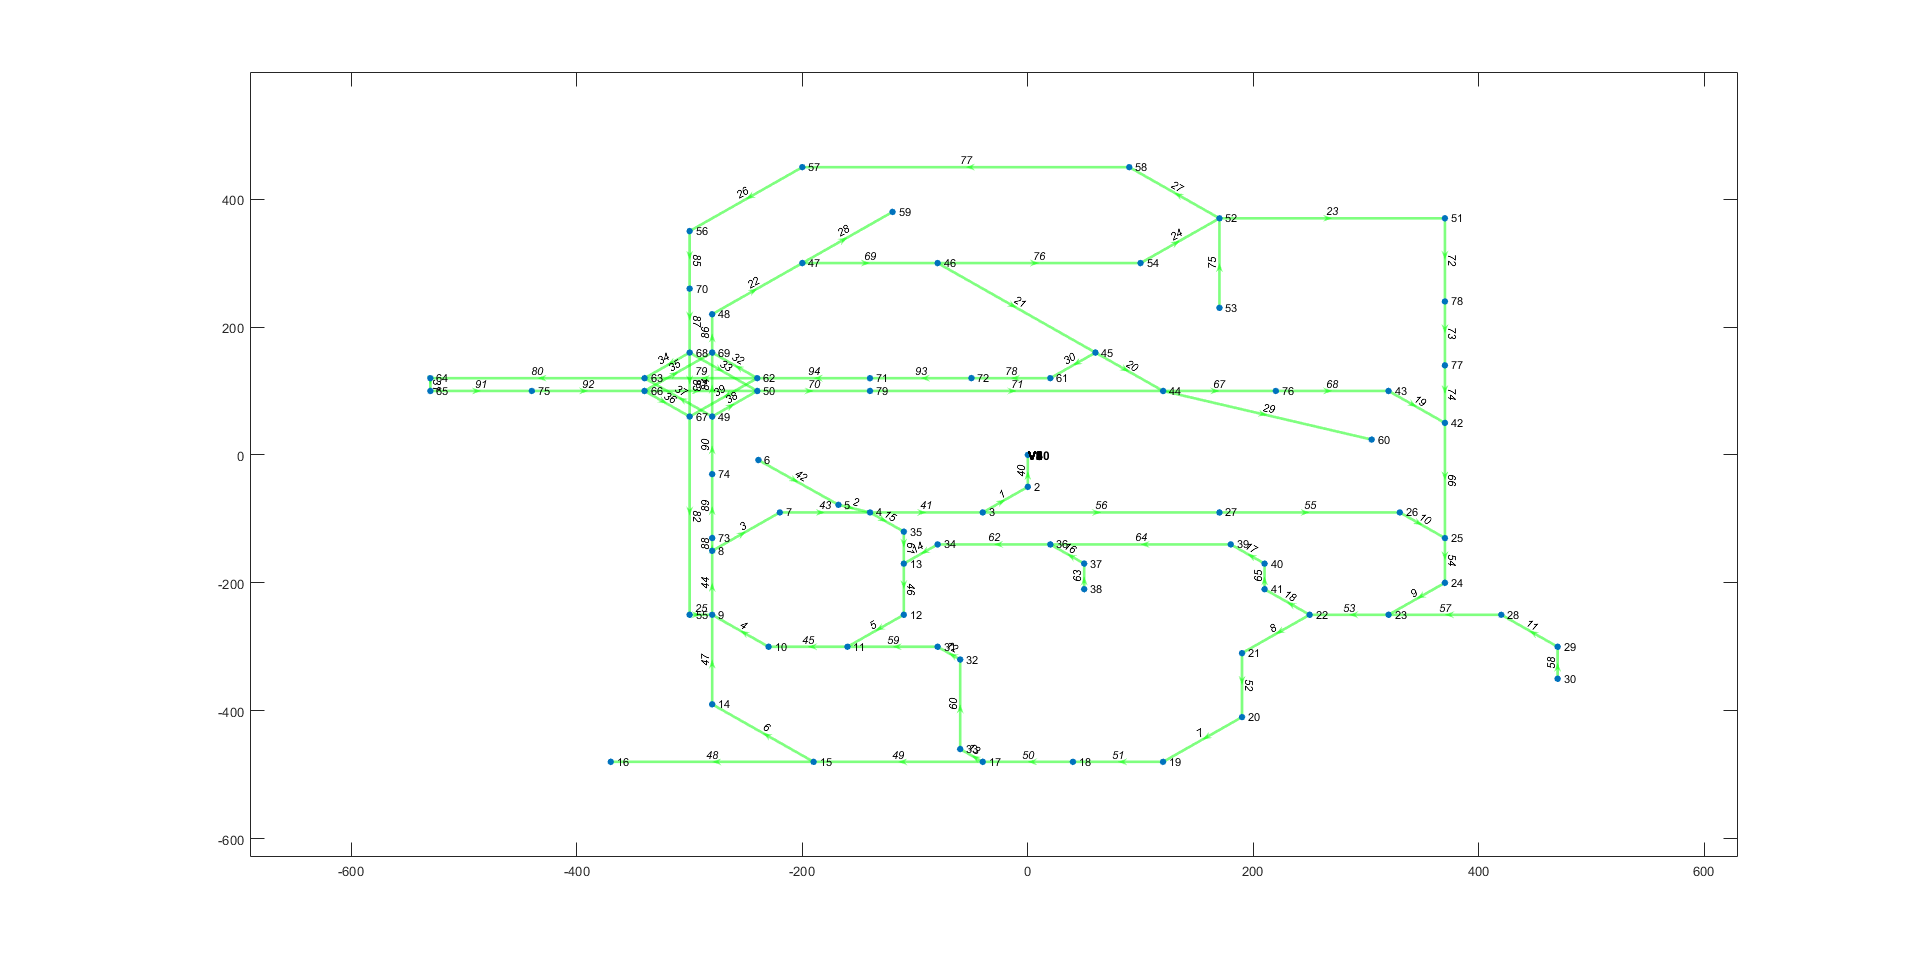

if ~exist('mapSelection','var')
    mapSelection = 'Mobatkent'; % Default map selection
end


if ~exist('scenarioSelection','var')
    scenarioSelection = 'Urban City Traffic'; % Default scenario selection
end

### Map Generation

The whole map concept is based on a *digraph* approach. To learn more about digraphs see: [https://www.mathworks.com/help/matlab/ref/digraph.html](https://www.mathworks.com/help/matlab/ref/digraph.html)

Basically we have nodes and edges. *Nodes* are used as *waypoints* and *edges* as the *routes* between those *nodes*.

The basic idea behind the traffic model in MOBATSim is explained here: [https://mobatsim.com/publications-and-articles/mobatsim-traffic-model/](https://mobatsim.com/publications-and-articles/mobatsim-traffic-model/)

Now let's get back to the code. This code makes sense when it is run from the `GUI` because in this workflow we have set the map to the default map: **Mobatkent**.

%% Choose/Load the Map
switch mapSelection  
    case 'Mobatkent'
        load_Mobatkent();   
        
    case 'Highway'
        open_system('Platoon_Event')
        
    case 'Crossmap'
        load_Crossmap();             
end

Now we have chosen our map. Please note that, at the moment we can obtain a map only for **Mobatkent** or **Crossmap**. **Mobatkent** also has a `3D animation Simulink model`, so it is the most complete map. **Highway** doesn't have a 2D map `plot` but it has a `3D animation` that runs during the runtime of the simulation. **Crossmap** on the other hand, has a 2D map `plot` but doesn't have a 3D animation.

Now let's generate the map. The formats of the map are quite a subject and will be most probably changed in the new version. The structure of the lines and curves are defined as matrices and their geometric properties so I will not go deep into that here. If you want to go through how it is generated, feel free to put a `breakpoint` and go inside the function with `F11` (Step in).

% Generate the Map
if exist('Map','var') 
    clear Map % Default map selection
    close all
end

Map = Map(mapName,waypoints, connections_circle,connections_translation, startingNodes, breakingNodes, stoppingNodes, leavingNodes);
set(gcf,'Visible','on') % specific to the live scripts, the external figure visibilities are set to "off" therefore we have to make it "on"

We have our map generated and stored. It should also appear on a `Figure` window. 

### Driving Scenario and the Vehicles

Next step is to load the *driving scenario* and initialize the `Vehicles`. Just like before, you can always put `breakpoints `and dive into the functions to see what is going inside if you are interested. This applies to all below.

%% Load Scenario and Vehicles
load_scenario(scenarioSelection);

% Load Vehicles
load_vehicles();

We have the map and the vehicles as seperate objects, now we have to insert these vehicles to the map.

%% Initialize Vehicles on the Map
Map.Vehicles = Vehicles; % Vehicles are attached to the Map instance
Map.initCarDescriptionPlot(); % Plots the initial positions of the vehicles on the map

From here on Simulink does the job. We have set the initial values and instances. It is worth mentioning that we have two types of classes. In the `src` directory you will find `MATLAB Classes` and `Simulink Classes`. The `Simulink Classes` are used for the `MATLAB System Blocks` in the Simulink models. Therefore, they are of a certain type and their structure is a bit different from the object oriented programming classes of MATLAB. However, we can use instances from the `MATLAB Classes` inside the `Simulink Classes`.

Now that we have generated the vehicles and the map, let's clear the unnecessary variables. This doesn't have much impact on the performance but it is still a good practice to keep our MATLAB `workspace` clean.

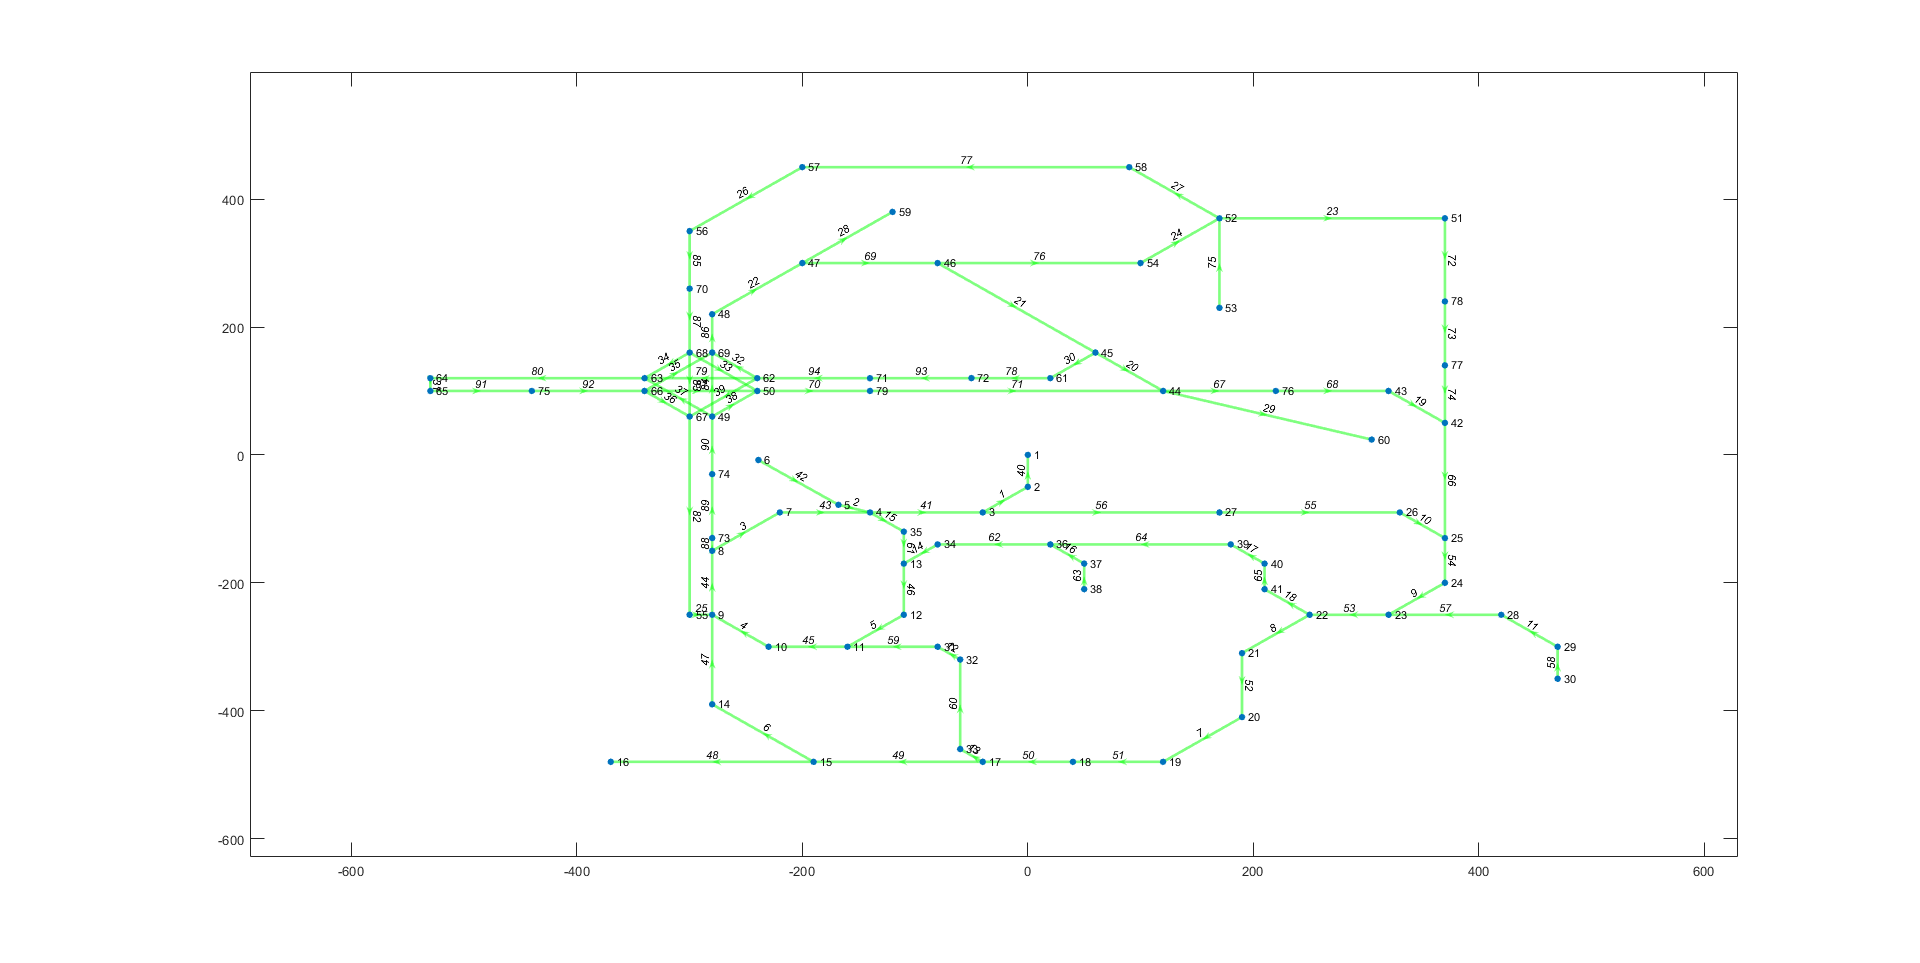

% Clear the initializing variables
clear_init_variables();

### Simulink Model

The `modelName` variable refers to the Simulink Model of the selected map.

% Open MOBATSim Simulink Model
open_system(modelName)

The fault injection properties were used for a previous project and will be removed. Here we set the default values required to run the simulation otherwise we would have errors. Soon to be fixed anyway.

% Fault Injection properties (TODO: To be implemented soon)
FI_distance = 0;
FI_speed = 0;
SafeDistance =18;

Now everything is ready for the simulation. You can either go to Simulink model and run it or you can run the last section of the code below. I would prefer running it from the model because otherwise this live script will try to draw a copy of the same map here below.

run_Sim();

## How to edit/analyze the simulation?

Now you know how to run the simulation. I will leave a few suggestions here so that you can better understand and change it.

### View the vehicle architectures

There are two main sources where the logic gets executed. One of them are the `.m file` scripts and the other ones are the Simulink models of the vehicles. They both work coordinated, as Simulink blocks use the created instances from the `Vehicle class` and overwrite their values. Here is how you can see the block diagram structure:

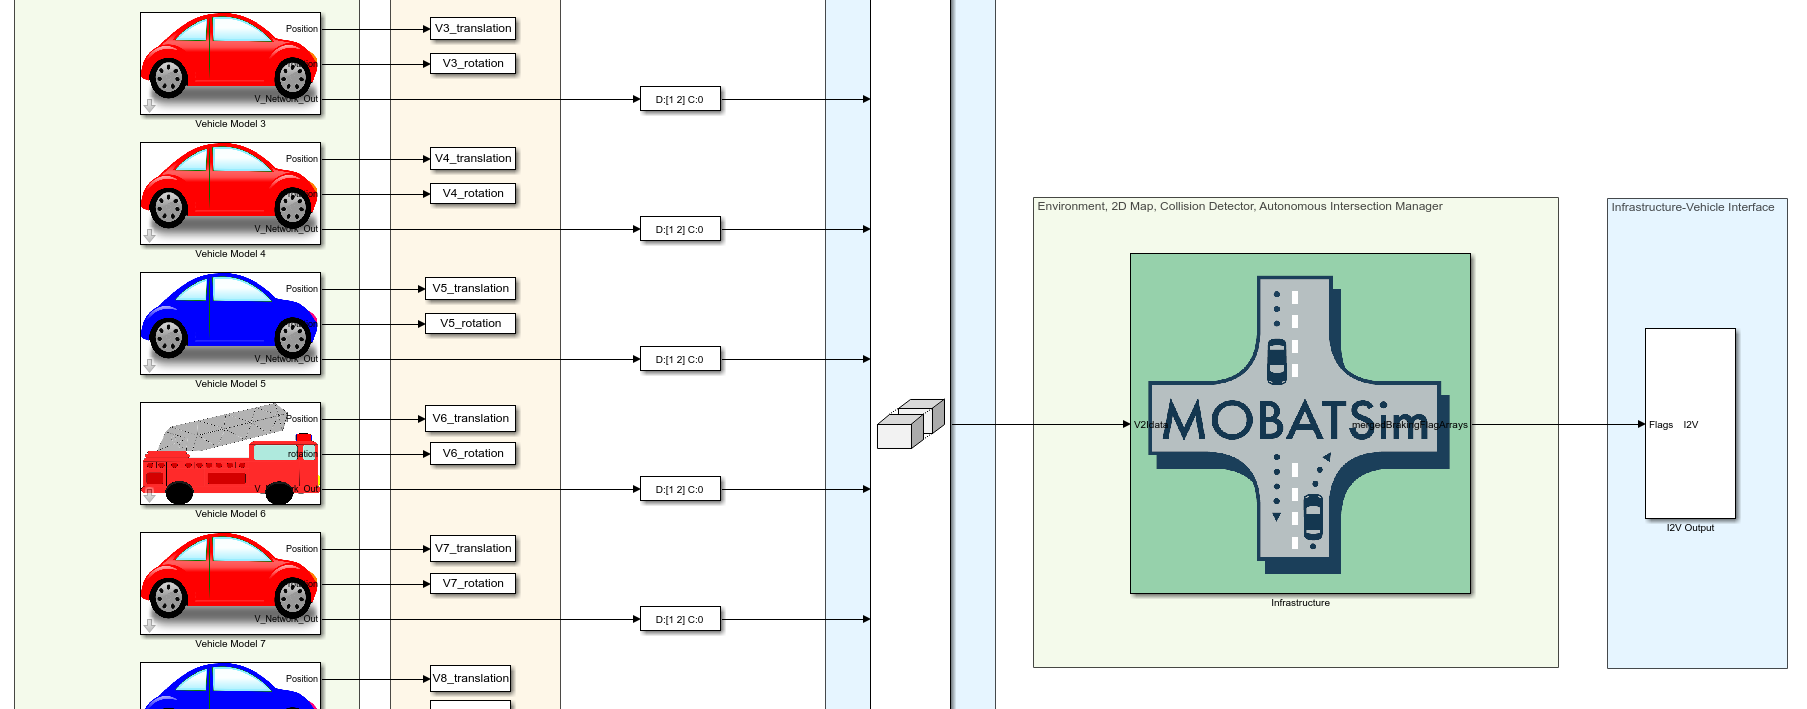

When you click on the small arrow on the lower left corner of the `Vehicle` block you should get this:

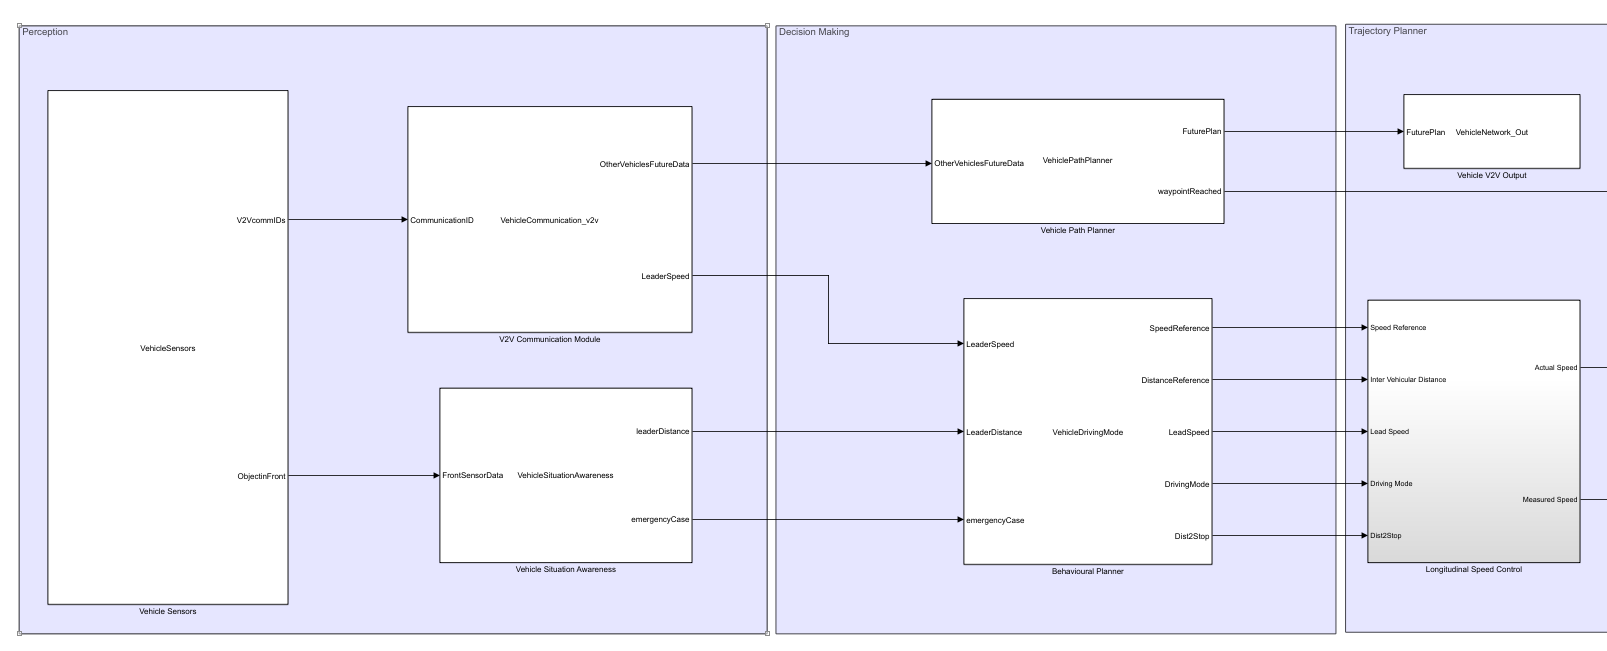

From here on, there are two main types of blocks. First one is the `MATLAB System Blocks` which take Simulink signals as inputs, run MATLAB codes and output signals. To see the code, double click on the block and click on the source code:

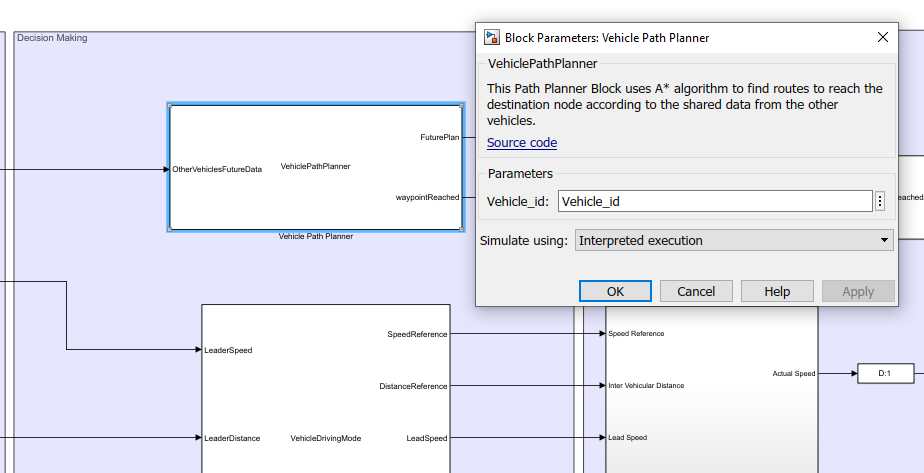

The `Vehicle_id` variable is the variable which keeps the ids of different vehicle from getting confused by the program. When you click on the `Source code`, you will see the `MATLAB System Block` code in the editor, which acts as a `Class` in itself but with a different set of properties to support the Simulink block type of execution. That is to run at every defined sample time according to the execution order.

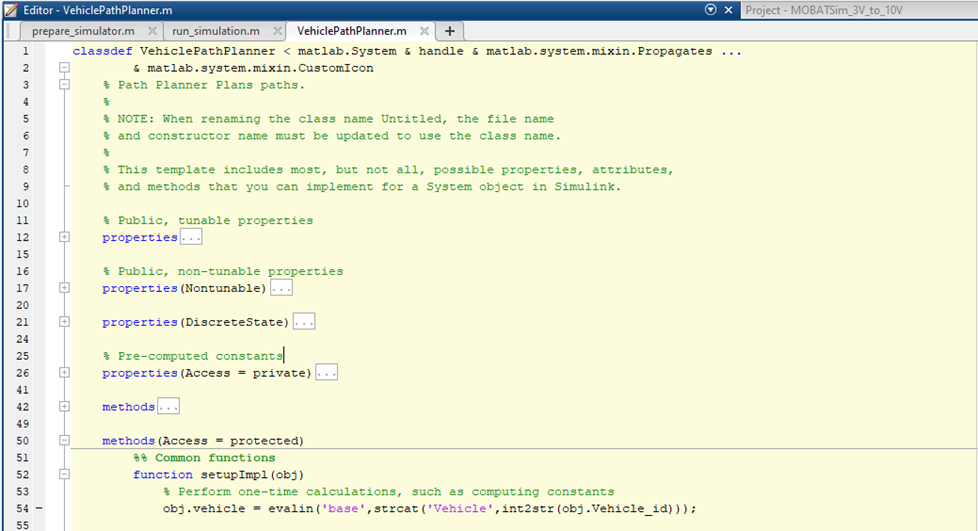

Here you can run the program by putting breakpoints. A useful tip is to put conditional breakpoints to view the execution at a certain time.

### Debugging the simulation

Best way to learn how variables change is to debug. Here you can run the program by putting breakpoints. A useful tip is to put conditional breakpoints to view the execution at a certain time. 

Right click here next to the code `line number`:

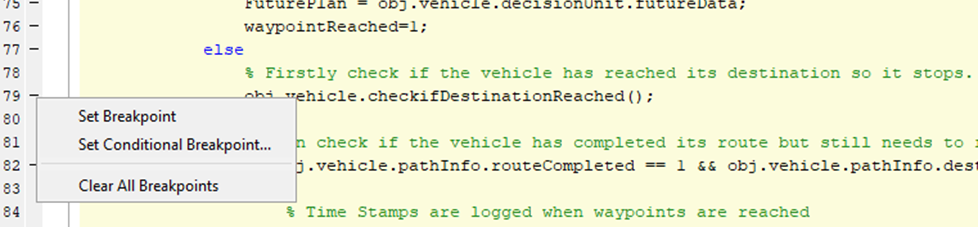

Choose `Set Conditional Breakpoint`. For example, to see `Vehicle 4` at or after time` t=6`, use the following condition:

- `obj.vehicle.id == 4 && get_param(obj.vehicle.modelName,'SimulationTime')>6`

Then when you rerun the simulation by starting with: 

clear all; 
clc; 

prepare_simulator(); 
run_Sim(); 

you will be in the debugging mode as here:

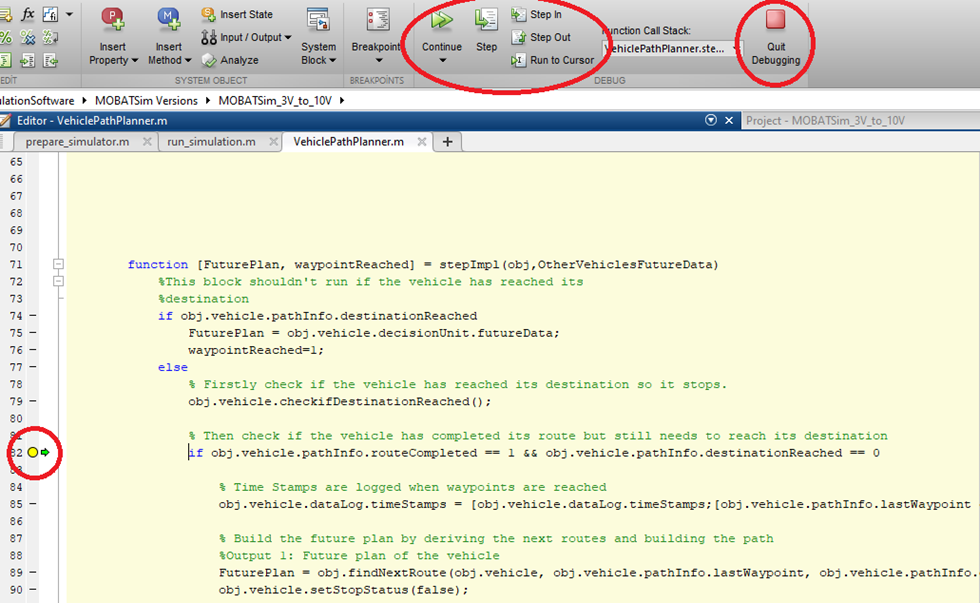

Then you can use the buttons above to go step by step debugging. At the mean time you can use the `command line` to the check variables:

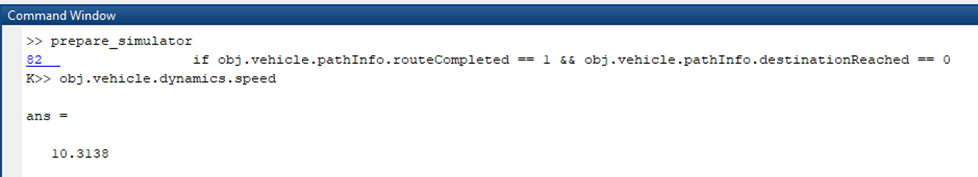

Here as you can see, we have seen the `speed` of `Vehicle 4`. To navigate the structure of a vehicle, please refer to Vehicle.m. You should learn a little bit about the `MATLAB Class structure `(OOP) and how to access variables to check. Let’s check it level by level:

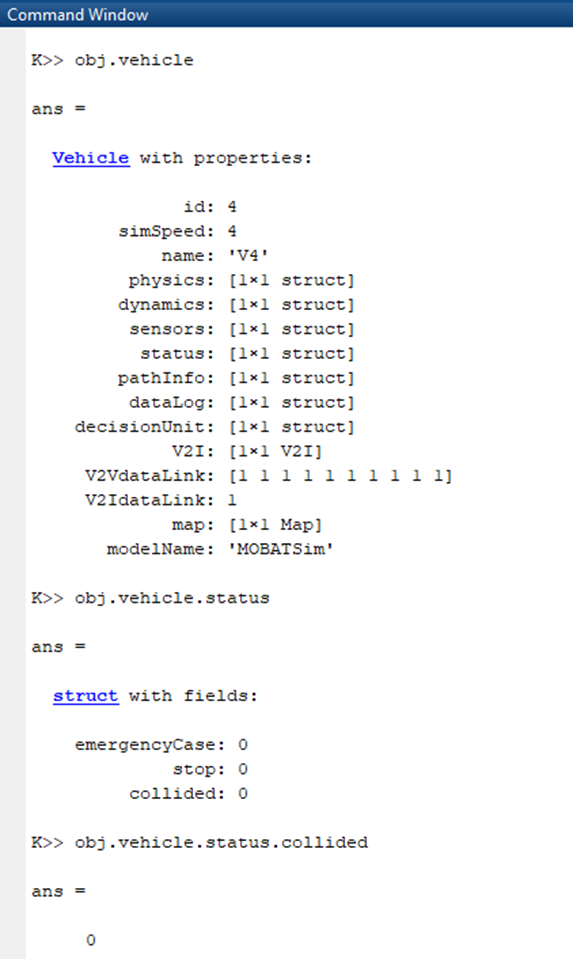

Now go ahead and try to find the initial driving scenario file. There you should see 10 `starting points` and `destination points` for 10 `vehicles`. Try to change some of them. Just note that the roads are one-way roads so the ending points should be reachable from the starting points. Otherwise, it throws an error. There are also some small bugs which happen at the intersection in a very rare cases. I will fix those things soon.

### Change the driving scenario

Let's try to change the *driving scenario*. We will have to find the script file for this, because a driving scenario is defines some of the `initial values` of the vehicles. You can simply look for the function: `load_scenario.m`. You will find it in the folder `src `and then `scripts`. There it is. Here is the portion of the code you might be interested in (it is commented out with % to make sure that it doesn't get executed when you run this script as a whole):

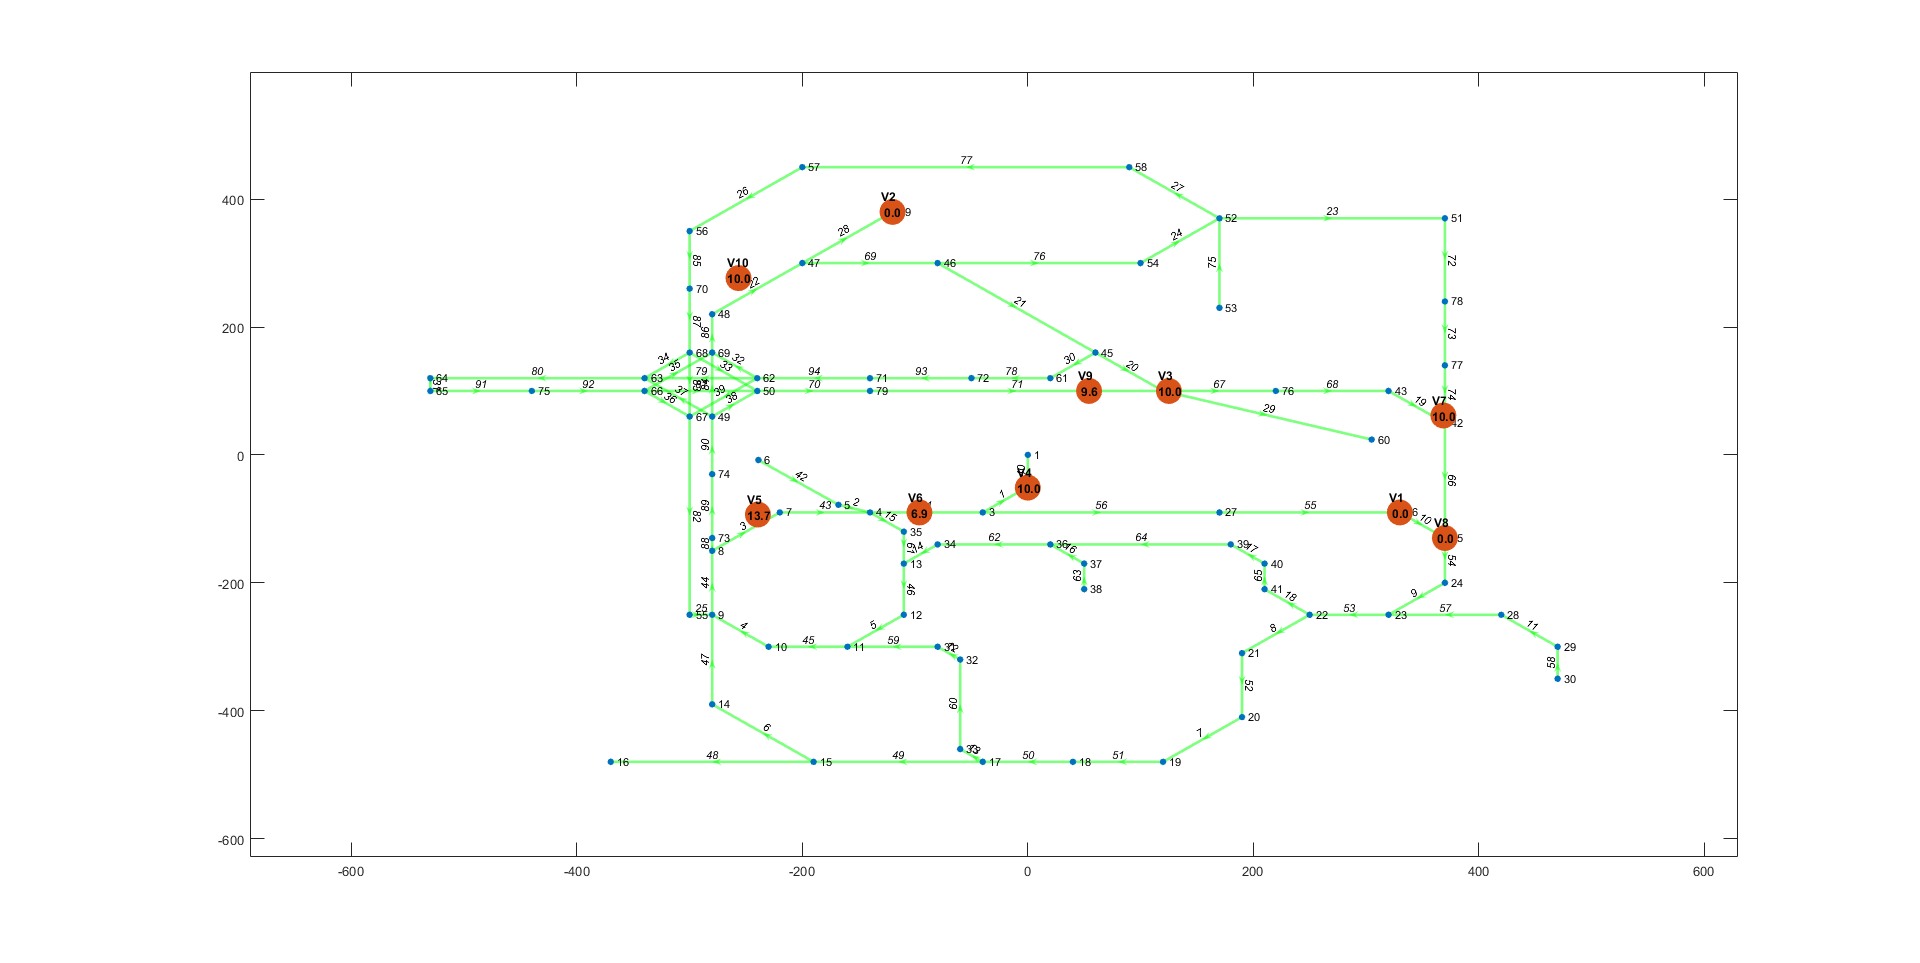

%case 'Urban City Traffic'
        %% complex crossroad scenario
        %startingPoints =    [8  46 61 18 54 52 64 6 15 63];
        %destinationPoints = [26 59 60 1  3  27 42 25 76 46];
        %maxSpeeds = [20 20 10 10 20 20 10 12 10 10];
        %SimTimeOut= '20';      

After you go through this code and understand how MOBATSim works, then you can just use the `MOBATSim.prj `file to run the project which automatically adds the required paths and starts a GUI where you can set some of the simulation parameters. If you have any further questions about any further parts of MOBATSim, just let me know!